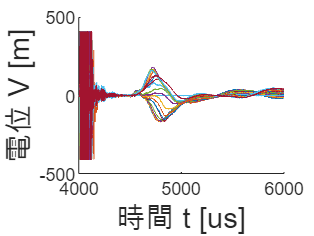

%時間-電位波形プロット

phi_t = zeros(19,2000);
t = 4001:6000;
figure;hold on
for i = 1:21
    filepath = strcat(...
        'C:\Users\Desktop\electroprobe\230712\shot\toroidal_mode20230712_No_p1','.csv');
    phi_t = readmatrix(filepath);
    plot(t,phi_t(t,i+1)*50);
    xlabel('時間 t [us]','FontSize',14)
    ylabel('電位 V [m]','FontSize',14)
end